# 1st Experiment

Ali Saeizadeh

810196477

3/17/2021

## Section 1

### Part 1

#### A.

format long
approximations = [2709/1024, 10583/4000, 2024/765]

approximations =    2.645507812500000   2.645750000000000   2.645751633986928


x = sqrt(7)

x =    2.645751311064591


[C, I] = min(abs(x - approximations))

C =      3.229223373146795e-07


I =      3


Best Fraction:

sym(approximations(I))

$$ans = \frac{2024}{765}$$

#### B.

format long
x = 3^301

x =     4.106744371757652e+143


sym_x = sym(x);
vpa(sym_x)

$$ans = 4.1067443717576516082036169417484e+143$$

sym_x

$$sym\_x = 410674437175765160820361694174843802787546092152263204276061421137680115001109947317381348595546423243177970334421273291830236683739419899854848$$

#### C.

20/3 - 20 * (1/3)

ans =      8.881784197001252e-16


Due to the limitation of registers of computers all fraction computed with an error. Here, Prority of divisions are higher than others, so 20/3 and 1/3 computed approximatley first, then the error of 1/3 multiplied by 20. so we can\t get coorect answer.

#### D.

10^16 + 1 - 10^16

ans =      0


This part is just like last one: fisrt of all $1 - 10^{16}$ will be compute beacuase 1 is so much lower than $10^{16
}$ MatLab will ignore it.

### Part 2

Just  *format long* function has been used.

#### A.

cosh(0.1)

ans =    1.005004168055804


#### B.

log(2)

ans =    0.693147180559945


#### C.

atan(0.5)

ans =    0.463647609000806


### Part 3

#### B.

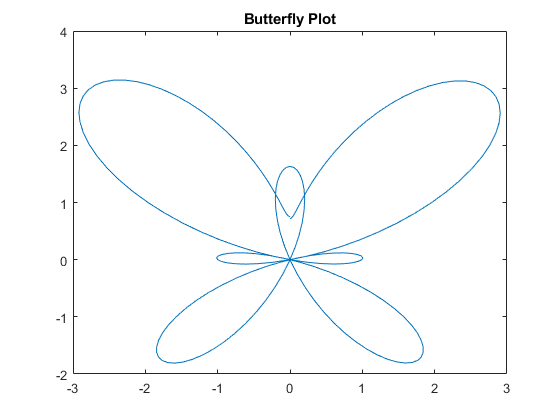

t1 = 0:pi/100:2*pi;
t2 = 0:pi/100:10*pi;
x1 = sin(t1) .* (exp(cos(t1)) - 2 .* cos(4 * t1) + sin(t1/12).^5);
y1 = cos(t1) .* (exp(cos(t1)) - 2 .* cos(4 * t1) + sin(t1/12).^5);

x2 = sin(t2) .* (exp(cos(t2)) - 2 .* cos(4 * t2) + sin(t2/12).^5);
y2 = cos(t2) .* (exp(cos(t2)) - 2 .* cos(4 * t2) + sin(t2/12).^5);
plot(x1,y1)
title 'Butterfly Plot'

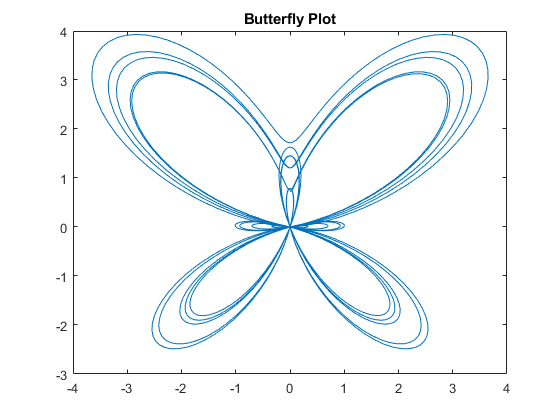

plot(x2,y2)
title 'Butterfly Plot'

## Section 2

### Part 1 

## Operator Precedence

- Parentheses `()`

- Transpose `(.')`, power `(.^)`, complex conjugate transpose `(')`, matrix power `(^)`

- Power with unary minus `(.^-)`, unary plus `(.^+)`, or logical negation `(.^~)` as well as matrix power with unary minus `(^-)`, unary plus `(^+)`, or logical negation `(^~)`.

- Unary plus `(+)`, unary minus `(-)`, logical negation `(~)`

- Multiplication `(.*)`, right division `(./)`, left division `(.\)`, matrix multiplication `(*)`, matrix right division `(/)`, matrix left division `(\)`

- Addition `(+)`, subtraction `(-)`

- Colon operator `(:)`

- Less than `(<)`, less than or equal to `(<=)`, greater than `(>)`, greater than or equal to `(>=)`, equal to `(==)`, not equal to `(~=)`

- Element-wise AND `(&)`

- Element-wise OR `(|)`

- Short-circuit AND `(&&)`

- Short-circuit OR `(||)`

operators have equal precedence and are evaluated from left to right

- 8/4 ---- 2

- 8/4 + 2 ------ 4

- 2 < 8/4 + 2 ----- 1

-  (2 < 8/4 + 2)^2 ------1

- 2 * (2 < 8/4 + 2)^2 ------- 2

- 2 * (2 < 8/4 + 2)^2 < (-2)^3 -------- False

2 * (2 < 8/4 + 2)^2 < (-2)^3

ans = logical
   0


- 5 + ~0 ------ 6

- (5 + ~0)/3 ------ 2

- 10/5 - 2 ------ 0

-  ~(10/5 - 2) ---------1

- 3 - ~(10/5 - 2) --------------2

- (5 + ~0)/3 == 3 - ~(10/5 - 2) -------------------- True

(5 + ~0)/3 == 3 - ~(10/5 - 2)

ans = logical
   1


- 12/6 ---------2 

- 0 >= 12/6 ------- False

- ~4 < 5 -------- True

- ~4 < 5|0 >= 12/6 ----------- True | False -------- 1

~4 < 5|0 >= 12/6

ans = logical
   1


- 15/3 --------- 5

- 2 + 3 ---------- 5

- 2 + 3 <= 15/3 ------------ 1

- -5 < -2 ------------ logical 1

- -7 < -5 < -2 ------------- False

- -7 < -5 < -2&2 + 3 <= 15/3 --------------------- False

-7 < -5 < -2&2 + 3 <= 15/3

ans = logical
   0


### Part 2

#### Pascal Triangle

n = 7

n =      7


K = zeros(n,n);
K(1,1) = 1;
K(2,1) = 1;
K(2,2) = 1;
for i= 3:1:n
    K(i,1) = 1;
    K(i,i) = 1;
    for j = 2:1:n-1
        K(i,j) = K(i-1,j-1) + K(i-1,j);
    end
end
K

K =      1     0     0     0     0     0     0
     1     1     0     0     0     0     0
     1     2     1     0     0     0     0
     1     3     3     1     0     0     0
     1     4     6     4     1     0     0
     1     5    10    10     5     1     0
     1     6    15    20    15     6     1


function code above(attached to files as *pascal_triangle.mlx)*

pascal_triangle(n)

ans =      1     0     0     0     0     0     0
     1     1     0     0     0     0     0
     1     2     1     0     0     0     0
     1     3     3     1     0     0     0
     1     4     6     4     1     0     0
     1     5    10    10     5     1     0
     1     6    15    20    15     6     1


### Part 3

Just using one loop:

n = 500;
A = zeros(n,n);
for i = 1:n
    A(i,:) = 1./(i:n+i-1);
end
max(eig(A))

ans =    2.376896505684826


Using No loops at all:

n = 500;
x = 1:1:n;
x = x-1;
y = 1:1:n;
A =  1./(x + transpose(y));
max(eig(A))

ans =    2.376896505684826


Functioning Code above: (attached to files named *magic_matrix.m*)

magic_matrix(n)

ans =    2.376896505684826


### Part 4

min_i = 10;
max_i = 30;
num = 20;
iter = 0;
cond = 1;

Initial Vector

x = min_i + randi(max_i - min_i,[1,num]);
display(x)

x =     23    15    26    12    16    27    14    23    21    29    16    12    25    26    29    29    11    15    23    29


while (cond ~= 0)
    y = mod(x,2) .* (min_i + randi(max_i - min_i,[1,num]));
    x = x .* ~mod(x,2);
    x = x + y;
    iter = iter + 1;
    cond = sum(mod(x,2));
end

Final Vector

display(x)

x =     30    22    26    12    16    20    14    28    24    24    16    12    14    26    20    22    22    22    16    22


text = 'The Vector Generated After %d Iterations';
str = sprintf(text,iter);
display(str)

str = 'The Vector Generated After 7 Iterations'